Post office packaging problem (M/M/c queue)

clear,clc;

Simulation

new_package_arrival_rate = 4;
regular_package_prob = 0.9;
packing_rate = 0.5;
num_workers = 9;
T = 2000;

% initialize variables
event_queue = EventQueue;
states = [];
regular_queue = PackageQueue(0); % no package in regular queue
priority_queue = PackageQueue(0); % no package in priority queue
workers = Workers(num_workers); % all workers are idle

t = 0;
event_queue = event_queue.schedule_new_package(t,new_package_arrival_rate); % schedule the first new package
states = [states; State(t,workers,regular_queue,priority_queue)]; % record simulation state

while t <= T
    [event_queue, t, event_type] = event_queue.pop();
    if event_type == "PackagePacked" % if a worker finishes packing
        if priority_queue.has_packages() % pack the next package in priority queue
            event_queue = event_queue.schedule_packing(t,packing_rate); % schedule packing to be finished
            priority_queue = priority_queue.release_one_package();
        elseif regular_queue.has_packages() % pack the next package in regular queue
            event_queue = event_queue.schedule_packing(t,packing_rate); % schedule packing to be finished
            regular_queue = regular_queue.release_one_package();
        else
            workers = workers.a_worker_becomes_idle();
        end
    elseif event_type == "NewPackage" % if a new package arrives
        event_queue = event_queue.schedule_new_package(t,new_package_arrival_rate); % schedule the next package
        if workers.has_idle_workers() % assign the new package to an idle worker
            event_queue = event_queue.schedule_packing(t,packing_rate); % schedule packaging to be finished
            workers = workers.a_worker_becomes_busy();
        elseif rand < regular_package_prob % new package is regular with probability
            regular_queue = regular_queue.add_one_package(); % put the new package in regular queue
        else
            priority_queue = priority_queue.add_one_package(); % put the new package in priority queue
        end
    end
    states = [states; State(t,workers,regular_queue,priority_queue)]; % record simulation state
end

Extract all variables in recorded states

timestamps = [states.time];
req_q_length = [states.req_q_length];
pri_q_length = [states.pri_q_length];
idle_workers = [states.idle_workers];

Sort all variables by timestamps (supposingly already sorted, but need to re-sort for unknown reason)

[timestamps, indices] = sort(timestamps);
req_q_length = req_q_length(indices);
pri_q_length = pri_q_length(indices);
idle_workers = idle_workers(indices);

Visualization TOFIX: The unknown lapping function problem

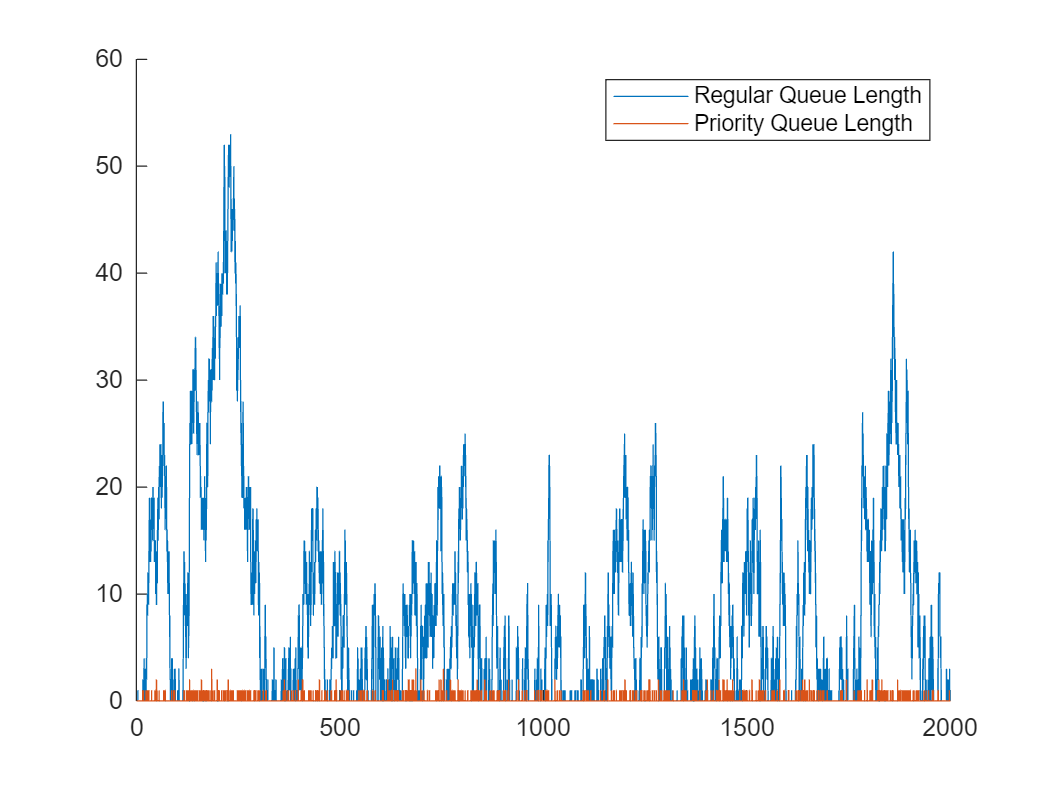

figure
hold on
stairs(timestamps,req_q_length);
stairs(timestamps,pri_q_length);
hold off
legend(["Regular Queue Length","Priority Queue Length"])
xlim([0,T]);

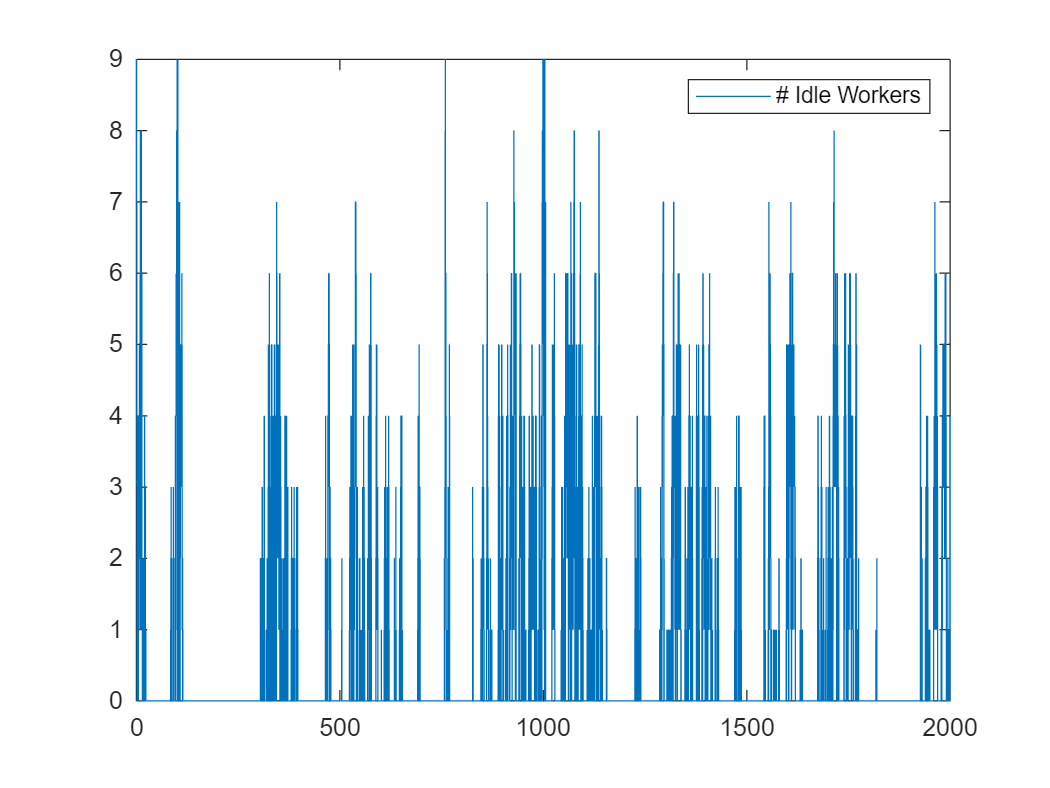

figure
stairs(timestamps,idle_workers);
legend("# Idle Workers")
xlim([0,T]);

Get time_intervals from timestamps

time_intervals = timestamps(2:end) - timestamps(1:end-1);

Analysis

workers_fully_utilized = (idle_workers == 0);
prop_fully_utilized = sum(time_intervals .* workers_fully_utilized(1:end-1)) / T;
fprintf('Proportion in time when workers are fully utilized: %.2f%%\n', prop_fully_utilized*100);

Proportion in time when workers are fully utilized: 74.52%


Analysis codes from Slava Vaisman mm1queue.m

N = 50; % batches
burnin_percentage = 0.000001;
states_struct = convert_array2struct(states);
states_matrix = cell2mat(struct2cell(states_struct))';

% calculate the step length of the step function
delta_time =  states_matrix(2:end,1) - states_matrix(1:end-1,1);
states_matrix = states_matrix(1:end-1,:);

[hatell, ci1, ci2] =  BatchMeanForStep(burnin_percentage, N, states_matrix(:,5), delta_time);
fprintf('Proportion in time when workers are fully utilized %.2f%% CI=(%.2f%%, %.2f%%)\n', hatell*100, ci1*100, ci2*100);

Proportion in time when workers are fully utilized 77.19% CI=(70.84%, 83.53%)


Supporting function codes from Slava Vaisman mm1queue.m

function states_struct = convert_array2struct(states)
    states_struct = [];
    for i=1:length(states)
        state.time = states(i).time;
        state.req_q_length = states(i).req_q_length;
        state.pri_q_length = states(i).pri_q_length;
        state.idle_workers = states(i).idle_workers;
        state.workers_fully_utilized = double(states(i).idle_workers == 0);
        states_struct = [states_struct; state];
    end
end

function [mu, CI_l, CI_r] = BatchMeanForStep(burnin_percentage,N,ell, step)
    K = floor(burnin_percentage*length(ell));
    ell_steady = ell(K+1:end);
    step_steady = step(K+1:end);
    batch_sz = floor(length(ell_steady)/N);
    ell_batch_mean = zeros(N,1);
    for i=1:N
        ell_tmp = ell_steady((i-1)*batch_sz + 1:i*batch_sz);
        step_tmp = step_steady((i-1)*batch_sz + 1:i*batch_sz);
        ell_batch_mean(i) = GetStepFunctionIntegral(ell_tmp, step_tmp)/sum(step_tmp);
    end
    [mu, CI_l, CI_r] = GetCI(ell_batch_mean)      ;
end

function res = GetStepFunctionIntegral(values, steps)
    res = sum(values.*steps);
end

function [mu, CI_l, CI_r] = GetCI(ell)
    n = length(ell);
    mu = mean(ell);
    S = std(ell);
    CI = [mu-1.96*S/sqrt(n),mu+1.96*S/sqrt(n)];
    CI_l = CI(1);
    CI_r = CI(2);
end